function C = concatenateAndFill(varargin)
    % 各列の長さを取得し、最大の長さを求める
    maxLength = max(cellfun(@length, varargin));

    % 各列について、足りない部分をNaNで埋める
    paddedColumns = cellfun(@(x) [x; NaN(maxLength-length(x),1)], varargin, 'UniformOutput', false);

    % すべての列を横に結合する
    C = horzcat(paddedColumns{:});
end

Figure 3A

% set index = 1 (max PHI) in MC_import
% set index = 2 (sum PHI) in MC_import

MC_import

ans =     15   326


ans =     16    12


ans =     16     3


ans =     18     1


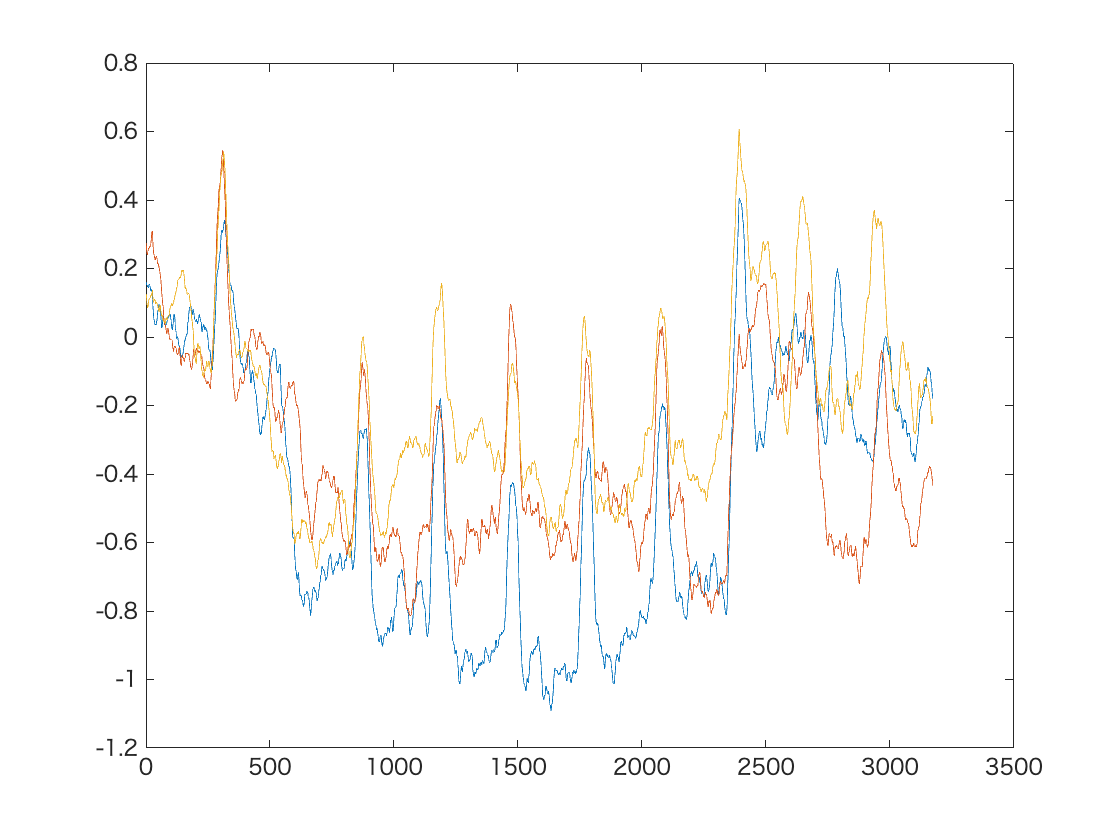


active_phi = zeros(18, time);
passive_phi = zeros(18, time);
control_phi = zeros(18, time);

for ind = 1 :18
    active_phi(ind, :) = movmean(active_PHI(ind, :), 50);
    passive_phi(ind, :) = movmean(passive_PHI(ind, :), 50);
    control_phi(ind, :) = movmean(control_PHI(ind, :), 50);
end

% Blue-Moderate: Red-Difficult: Yellow-Easy
result = [mean(active_phi);mean(passive_phi);mean(control_phi)].';

writematrix(result, "maxPhi_series_" + num2str(interval) + ".csv");

hold off
plot(mean(active_phi))
hold on
plot(mean(passive_phi))
plot(mean(control_phi))
hold off

Figure 3B

% set index = 4 (sum PHI) in MC_import

MC_import

MC_type = unique([unique_without_nan(active_MC); ...
    unique_without_nan(passive_MC); unique_without_nan(control_MC)]); 

times = 1: time1;

inter = size(active_PHI(:,times), 2);
active_bf = reshape(active_MC(:, times), [1, inter*18]);
passive_bf = reshape(passive_MC(:, times), [1, inter*18]);
control_bf = reshape(control_MC(:, times), [1, inter*18]);

active_mip_bf = reshape(active_PHI(:, times), [1, inter*18]);
passive_mip_bf = reshape(passive_PHI(:, times), [1, inter*18]);
control_mip_bf = reshape(control_PHI(:, times), [1, inter*18]);

times = time1:time2;

inter = size(active_MC(:,times), 2);
active_task = reshape(active_MC(:, times), [1, inter*18]);
passive_task = reshape(passive_MC(:, times), [1, inter*18]);
control_task = reshape(control_MC(:, times), [1, inter*18]);

active_mip_task = reshape(active_PHI(:, times), [1, inter*18]);
passive_mip_task = reshape(passive_PHI(:, times), [1, inter*18]);
control_mip_task = reshape(control_PHI(:, times), [1, inter*18]);

times = time2:3173;

inter = size(active_MC(:,times), 2);
active_af = reshape(active_MC(:, times), [1, inter*18]);
passive_af = reshape(passive_MC(:, times), [1, inter*18]);
control_af = reshape(control_MC(:, times), [1, inter*18]);

active_mip_af = reshape(active_PHI(:, times), [1, inter*18]);
passive_mip_af = reshape(passive_PHI(:, times), [1, inter*18]);
control_mip_af = reshape(control_PHI(:, times), [1, inter*18]);


% Fig SUMPHI during task

x1 = active_mip_task.';
x2 = passive_mip_task.';
x3 = control_mip_task.';
[kstest(x1),kstest(x2),kstest(x3)]

ans = 1×3 の logical 配列
   1   1   1



x = [x1; x3; x2];
g = [zeros(length(x1), 1); ones(length(x3), 1); 2*ones(length(x2), 1)];
%boxplot(x, g)

% Moderate, Easy, Difficult
[mean(x1), mean(x3), mean(x2)]

ans =    -0.7520   -0.3602   -0.4899



[p,tbl,stats] = kruskalwallis([x1, x3, x2], [],'off')

p = 3.5425e-252

tbl = 4×6 の cell 配列
    {'ソース'}    {'SS'        }    {'df'   }    {'MS'        }    {'カイ 2 乗'  }    {'確率>カイ 2 乗'}
    {'列'   }    {[9.0766e+11]}    {[    2]}    {[4.5383e+11]}    {[1.1580e+03]}    {[  3.5425e-252]}
    {'エラー'}    {[7.5111e+13]}    {[96981]}    {[7.7449e+08]}    {0×0 double  }    {0×0 double     }
    {'総数' }    {[7.6018e+13]}    {[96983]}    {0×0 double  }    {0×0 double  }    {0×0 double     }


stats = フィールドをもつ struct :
       gnames: [3×1 char]
            n: [32328 32328 32328]
       source: 'kruskalwallis'
    meanranks: [4.4765e+04 5.2258e+04 4.8454e+04]
         sumt: 1200


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


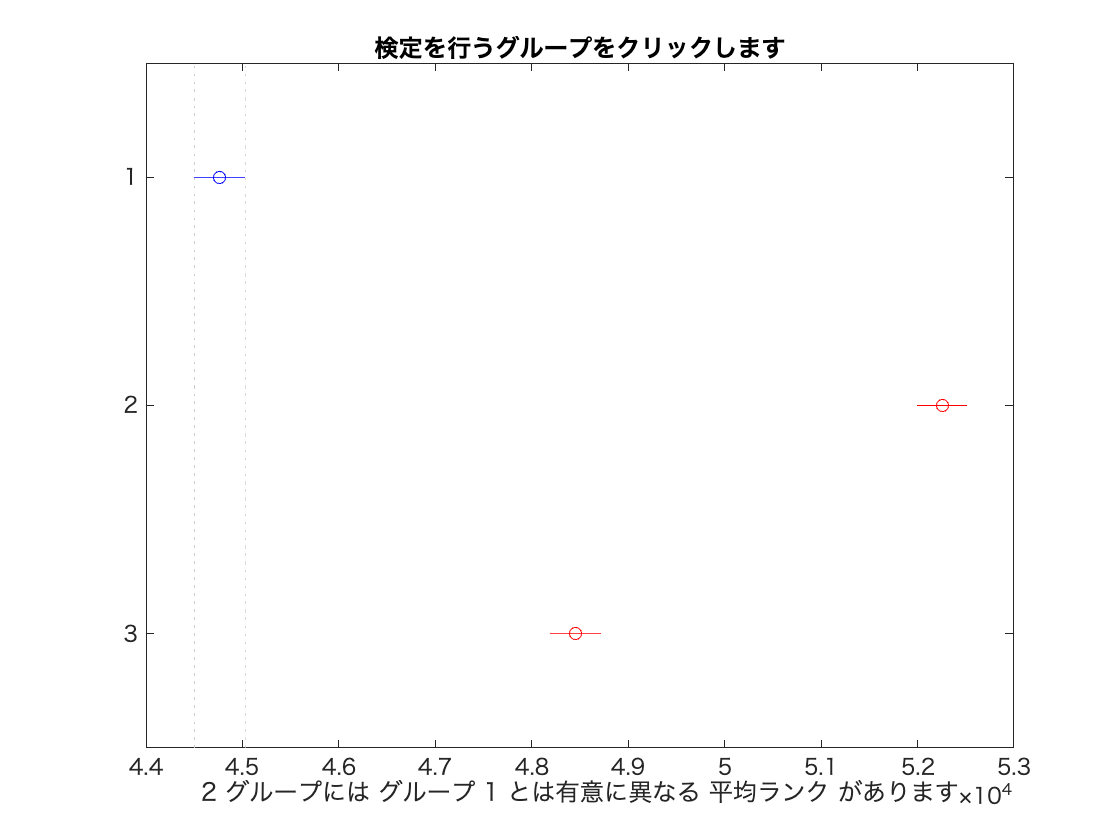

c = 1.0e+03 *

    0.0010    0.0020   -8.0190   -7.4932   -6.9674         0
    0.0010    0.0030   -4.2150   -3.6892   -3.1634         0
    0.0020    0.0030    3.2782    3.8040    4.3298         0


c = multcompare(stats,"CriticalValueType","dunn-sidak")


writematrix([x1,x3, x2], "ANOVA.csv")

% Fig SUMPHI post task

x1 = active_mip_af.';
x2 = passive_mip_af.';
x3 = control_mip_af.';
[kstest(x1),kstest(x2),kstest(x3)]

ans = 1×3 の logical 配列
   1   1   1


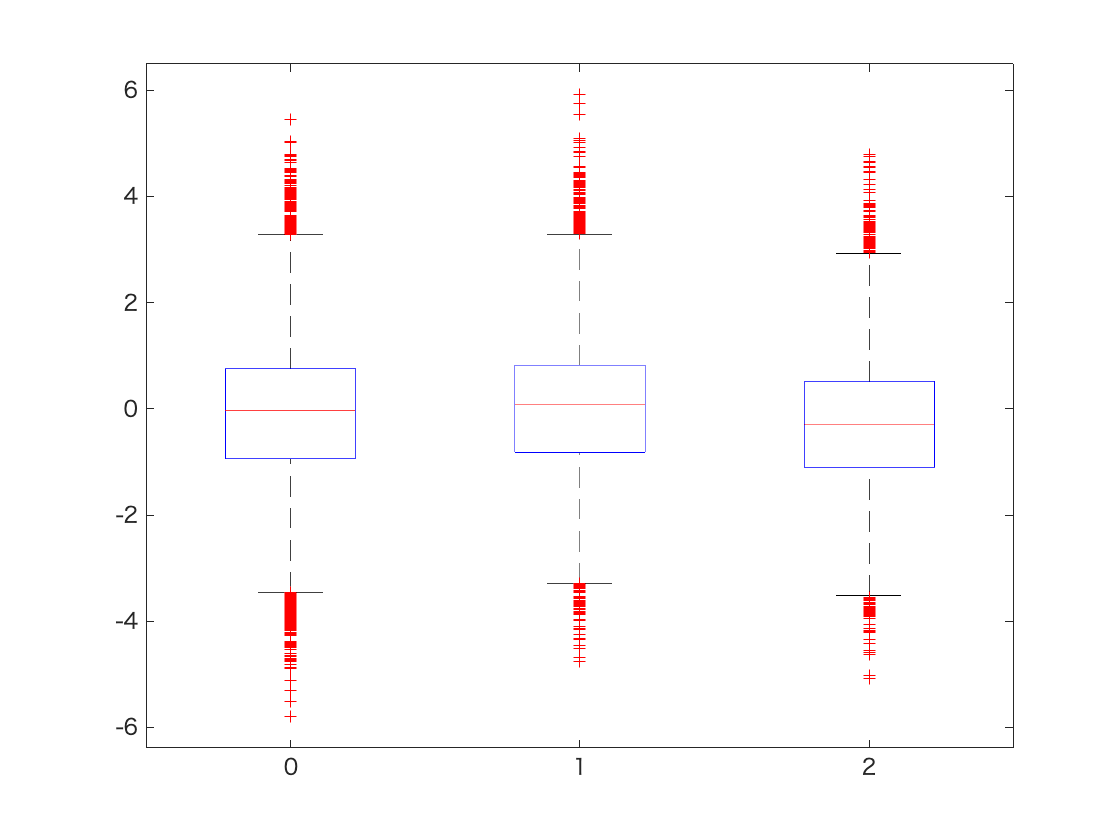


x = [x1; x3; x2];
g = [zeros(length(x1), 1); ones(length(x3), 1); 2*ones(length(x2), 1)];
boxplot(x, g)


% Moderate, Difficult, Easy
[mean(x1), mean(x3), mean(x2)]

ans =    -0.1133    0.0392   -0.2866


[p,tbl,stats] = kruskalwallis([x1, x3, x2],[],'off')

p = 1.2323e-115

tbl = 4×6 の cell 配列
    {'ソース'}    {'SS'        }    {'df'   }    {'MS'        }    {'カイ 2 乗'}    {'確率>カイ 2 乗'}
    {'列'   }    {[8.3954e+10]}    {[    2]}    {[4.1977e+10]}    {[529.1768]}    {[  1.2323e-115]}
    {'エラー'}    {[6.8381e+12]}    {[43629]}    {[1.5673e+08]}    {0×0 double}    {0×0 double     }
    {'総数' }    {[6.9220e+12]}    {[43631]}    {0×0 double  }    {0×0 double}    {0×0 double     }


stats = フィールドをもつ struct :
       gnames: [3×1 char]
            n: [14544 14544 14544]
       source: 'kruskalwallis'
    meanranks: [2.2132e+04 2.3336e+04 1.9982e+04]
         sumt: 0


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


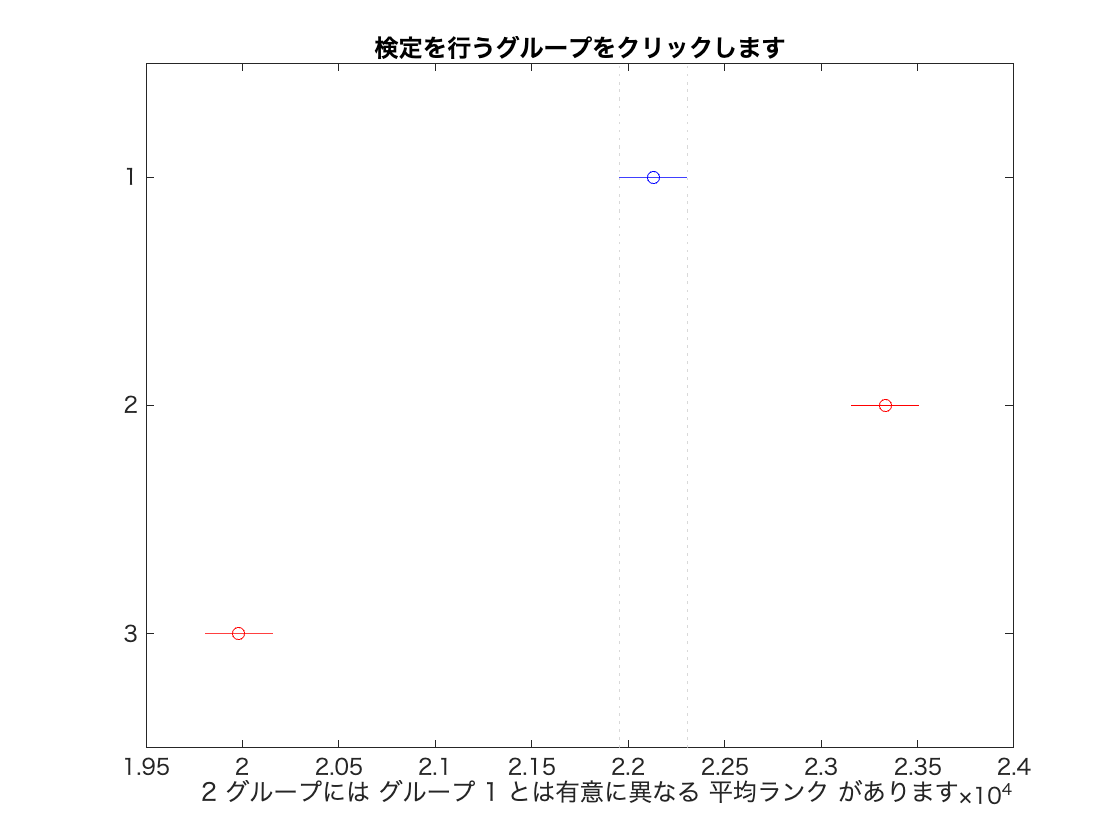

c = 1.0e+03 *

    0.0010    0.0020   -1.5566   -1.2039   -0.8512    0.0000
    0.0010    0.0030    1.7970    2.1497    2.5024         0
    0.0020    0.0030    3.0009    3.3536    3.7063         0


c = multcompare(stats,"CriticalValueType","dunn-sidak")


writematrix([x1,x2, x3], "ANOVA.csv")

Figure 3C

メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


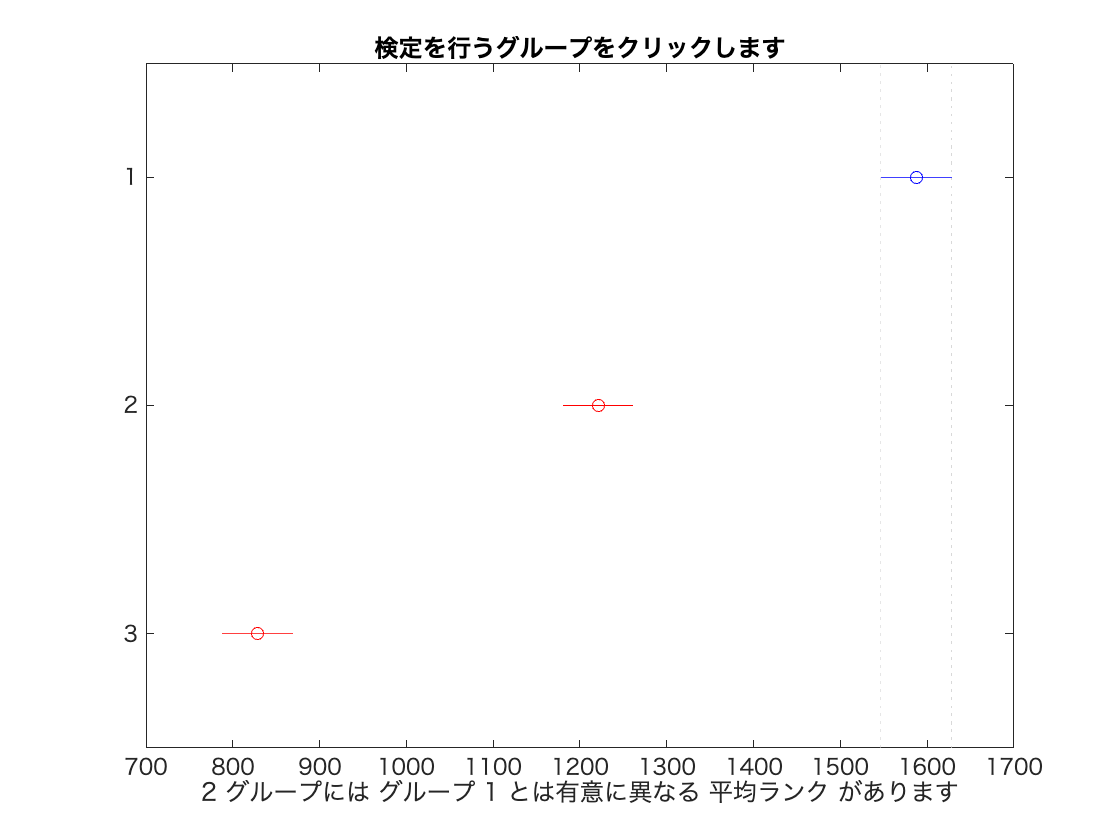

% set time
t1 = times(2);  t2= times(3); t_end=times(1);
t1_interval = 1:t1; t2_interval = t1:t2; t3_interval = t2:t_end;

task_phi_ind = zeros(18, 3);
post_phi_ind = zeros(18, 3);

p_values_task = zeros(18, 3);
p_values_post = zeros(18, 3);

for ind = 1 : 18
    X2 = [active_PHI(ind, t2_interval); control_PHI(ind, t2_interval); passive_PHI(ind, t2_interval)].';
    X3 = [active_PHI(ind, t3_interval); control_PHI(ind, t3_interval); passive_PHI(ind, t3_interval)].';

    task_phi_ind(ind, : ) = mean(X2);
    post_phi_ind(ind, : ) = mean(X3);

    [p2,tbl,stats] = kruskalwallis(X2,[],'off');
    c = multcompare(stats);
    p_values_task(ind, :) = c(:, 6).';
    [p3,tbl,stats] = kruskalwallis(X3,[],'off');
    c = multcompare(stats);
    p_values_post(ind, :) = c(:, 6).';
end

%% Order
% 1-Moderate 2-Easy 3-Difficult
% active-control, active-passive, control-passive

series = zeros(1, 6);
series2 = zeros(1, 6);

type_series = [[1, 2, 3]; [1, 3, 2]; [2, 1, 3]; [2, 3, 1]; [3, 1, 2]; [3, 2, 1]];

 [~, index] = sort(task_phi_ind,2);
 [~, index2] = sort(post_phi_ind,2);

 for ind = 1 : 18
     for j = 1: 6
         if sum(type_series(j, : ) == index(ind, :)) == 3
             series(j) = series(j) + 1;
         end
         if sum(type_series(j, : ) == index2(ind, :)) == 3
             series2(j) = series2(j) + 1;
         end
     end
 end
 
 X = [[series/sum(series);series2/sum(series2)].']

X =     0.2222    0.1667
    0.3889    0.1111
    0.1111    0.0556
         0    0.1111
    0.1111    0.3333
    0.1667    0.2222


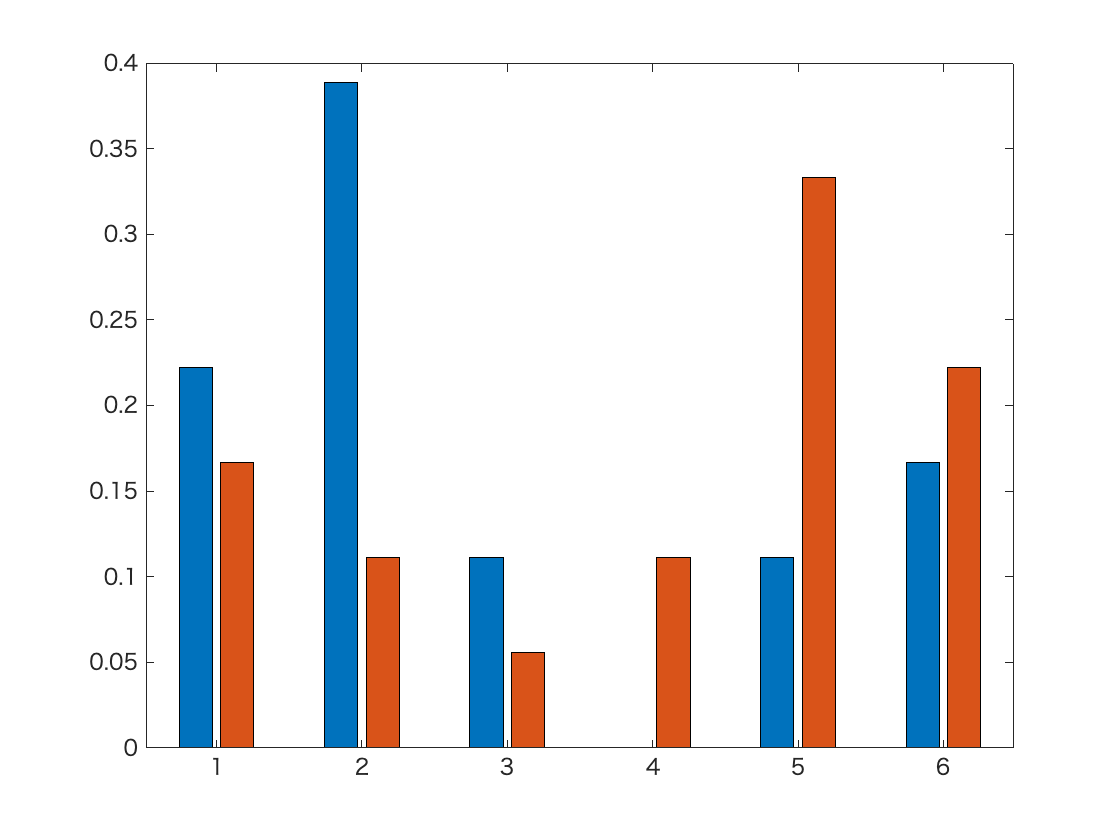

 
 bar(X)

Table 2 : Max PHI test for each Main Complex

% select 6 or 23
cp1 = 23;
bit_seq_rev(cp1)

ans = 1×4 の string 配列
    "Fz"    "Cz"    "Pz"    "EDA"



mip_active_task = active_mip_task(find(active_task==cp1));
mip_passive_task = passive_mip_task(find(passive_task==cp1));
mip_control_task = control_mip_task(find(control_task==cp1));

x1 = (mip_active_task).';
x2 = (mip_passive_task).';
x3 = (mip_control_task).';
x = [x1; x2; x3];

[mean(x1), mean(x2), mean(x3)]

ans =    -1.3536   -0.9891   -0.7554


[std(x1), std(x2), std(x3)]

ans =     1.0679    1.0201    0.9010



result = concatenateAndFill(x1, x2, x3);
[p,tbl,stats] = kruskalwallis(result, [],'off')

p = 1.0287e-115

tbl = 4×6 の cell 配列
    {'ソース'  }    {'SS'        }    {'df'  }    {'MS'        }    {'カイ 2 乗'}    {'確率>カイ 2 乗'}
    {'グループ'}    {[4.0622e+09]}    {[   2]}    {[2.0311e+09]}    {[529.5379]}    {[  1.0287e-115]}
    {'エラー'  }    {[6.9528e+10]}    {[9591]}    {[7.2493e+06]}    {0×0 double}    {0×0 double     }
    {'総数'   }    {[7.3590e+10]}    {[9593]}    {0×0 double  }    {0×0 double}    {0×0 double     }


stats = フィールドをもつ struct :
       gnames: {3×1 cell}
            n: [3390 3590 2614]
       source: 'kruskalwallis'
    meanranks: [4.0000e+03 4.9410e+03 5.6347e+03]
         sumt: 0


メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


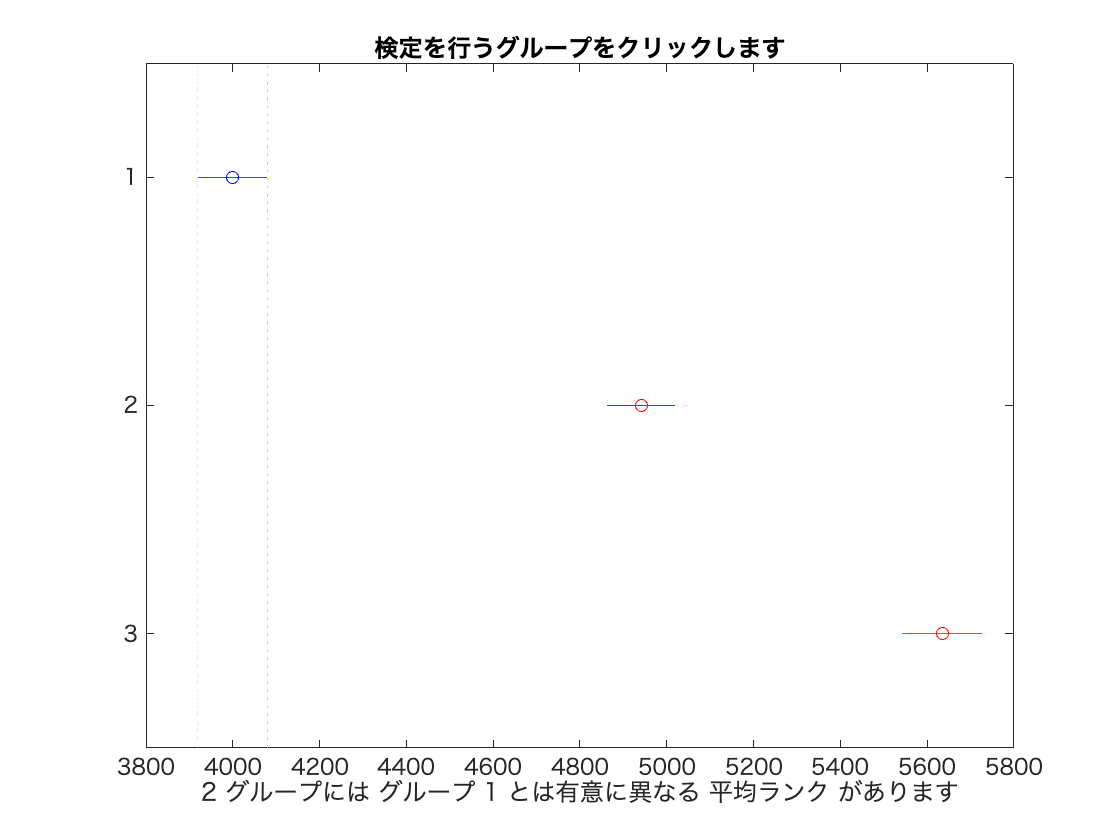

c = 1.0e+03 *

    0.0010    0.0020   -1.0994   -0.9410   -0.7826         0
    0.0010    0.0030   -1.8068   -1.6347   -1.4626         0
    0.0020    0.0030   -0.8637   -0.6937   -0.5236         0


c = multcompare(stats,"CriticalValueType","dunn-sidak")

writematrix(result, "ANOVA.csv")

Figure 4

% set index = 4 (sum PHI) in MC_import

MC_import;

MC_type = unique([unique_without_nan(active_MC); ...
    unique_without_nan(passive_MC); unique_without_nan(control_MC)]);

MC_frequency_Prev = zeros(3, size(MC_type, 1), 18);
MC_frequency_Stim = zeros(3, size(MC_type, 1), 18);
MC_frequency_Post = zeros(3, size(MC_type, 1), 18);

% 時間設定
t1 = times(2);  t2= times(3); t_end=times(1);
t1_interval = 1:t1; t2_interval = t1:t2; t3_interval = t2:t_end;

T1 = length(t1_interval);
T2 = length(t2_interval);
T3 = length(t3_interval);


for ind = 1 :18
    for i = 1 : length(MC_type)
        MC_frequency_Prev(1, i, ind) = sum(active_MC(ind, t1_interval)==MC_type(i))/T1;
        MC_frequency_Prev(2, i, ind) = sum(passive_MC(ind, t1_interval)==MC_type(i))/T1;
        MC_frequency_Prev(3, i, ind) = sum(control_MC(ind, t1_interval)==MC_type(i))/T1;
    
        MC_frequency_Stim(1, i, ind) = sum(active_MC(ind, t2_interval)==MC_type(i))/T2;
        MC_frequency_Stim(2, i, ind) = sum(passive_MC(ind, t2_interval)==MC_type(i))/T2;
        MC_frequency_Stim(3, i, ind) = sum(control_MC(ind, t2_interval)==MC_type(i))/T2;
    
        MC_frequency_Post(1, i, ind) = sum(active_MC(ind, t3_interval)==MC_type(i))/T3;
        MC_frequency_Post(2, i, ind) = sum(passive_MC(ind, t3_interval)==MC_type(i))/T3;
        MC_frequency_Post(3, i, ind) = sum(control_MC(ind, t3_interval)==MC_type(i))/T3;
    end
end

%%
mean_stim_bar = zeros(length(MC_type), 3);
MC_list = [];

for j = 1 : length(MC_type)
    count = [0, 0, 0];
    for i = 1 : 3
        A = reshape(MC_frequency_Stim(i, j, :) - MC_frequency_Prev(i, j, :), [18, 1]);
        if swtest(A, 0.05) == 0
            [s, p] = ttest(A, zeros(18,1));
        else
            [p, h] = ranksum(A, zeros(18,1));
        end
        mean_stim_bar(j, i) = mean(A);

        if p < 0.05
            count(i) = 1;
        end
    end

    if sum(count) >= 1 && mean(abs(mean_stim_bar(j, :))) > 0.005
        MC_list = [MC_list, j];
        [MC_type(j), bit_seq_rev(MC_type(j))]
        count
    end
end

ans = 1×3 の string 配列
    "3"    "Fz"    "Cz"


count =      1     1     0


ans = 1×3 の string 配列
    "5"    "Fz"    "Pz"


count =      0     0     1


ans = 1×3 の string 配列
    "6"    "Cz"    "Pz"


count =      1     1     1


ans = 1×3 の string 配列
    "17"    "Fz"    "EDA"


count =      0     1     1


ans = 1×3 の string 配列
    "18"    "Cz"    "EDA"


count =      1     1     0


ans = 1×4 の string 配列
    "19"    "Fz"    "Cz"    "EDA"


count =      1     1     1


ans = 1×3 の string 配列
    "20"    "Pz"    "EDA"


count =      1     1     0


ans = 1×4 の string 配列
    "21"    "Fz"    "Pz"    "EDA"


count =      1     1     1


ans = 1×4 の string 配列
    "22"    "Cz"    "Pz"    "EDA"


count =      1     1     0


ans = 1×5 の string 配列
    "23"    "Fz"    "Cz"    "Pz"    "EDA"


count =      1     1     1


ans = 1×5 の string 配列
    "27"    "Fz"    "Cz"    "ECG"    "EDA"


count =      1     0     0


ans = 1×6 の string 配列
    "31"    "Fz"    "Cz"    "Pz"    "ECG"    "EDA"


count =      1     1     0




mean_post_bar = zeros(length(MC_type), 3);
MC_list = [];

for j = 1 : length(MC_type)
    count = [0, 0, 0];
    for i = 1 : 3
        A = reshape(MC_frequency_Post(i, j, :) - MC_frequency_Prev(i, j, :), [18, 1]);
        [s, p] = ttest(A, zeros(18,1));
        if swtest(A, 0.05) == 0
            [s, p] = ttest(A, zeros(18,1));
        else
            [p, h] = ranksum(A, zeros(18,1));
        end

        mean_post_bar(j, i) = mean(A);
        if p < 0.05
            count(i) = 1;
        end
    end
    if sum(count) >= 1 && mean(abs(mean_post_bar(j, :))) > 0.005
        MC_list = [MC_list, j];
        bit_seq_rev(MC_type(j))
        count
    end
end

ans = 1×2 の string 配列
    "Fz"    "Cz"


count =      0     0     1


ans = 1×2 の string 配列
    "Cz"    "Pz"


count =      0     1     0


ans = 1×3 の string 配列
    "Fz"    "Cz"    "Pz"


count =      0     0     1


ans = 1×5 の string 配列
    "Fz"    "Cz"    "Pz"    "ECG"    "EDA"


count =      0     1     1


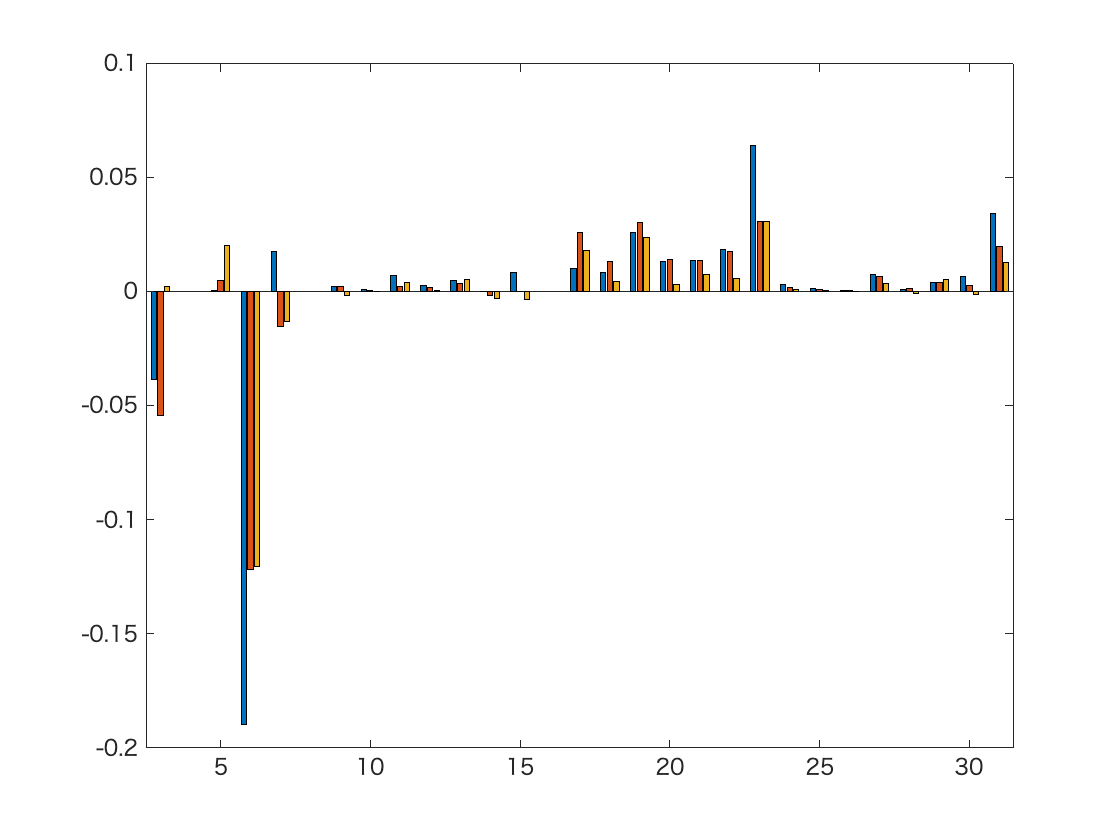


bar(MC_type, mean_stim_bar)